Create software program that can encrypt and decrypt message using DES (2 Round Only). Test data: use plaintext, ciphertext, and key generation.

Values of **K, P8 & P10 **are set according to Lec.3

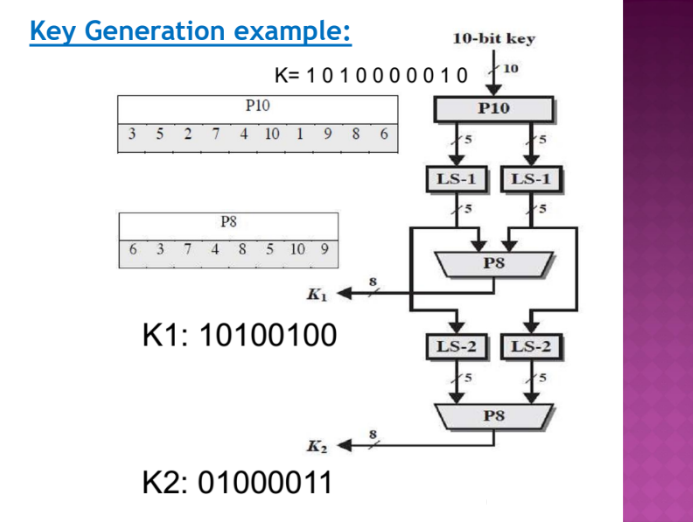

**1- Key Generation**

IV   = [1 0 1 0 0 0 0 0 1 0];
p_10 = [3 5 2 7 4 10 1 9 8 6];
p_8  = [6 3 7 4 8 5 10 9];
[K1,K2] = SDES_Key_Generation(p_8,p_10,IV)

K1 =      1     0     1     0     0     1     0     0


K2 =      0     1     0     0     0     0     1     1


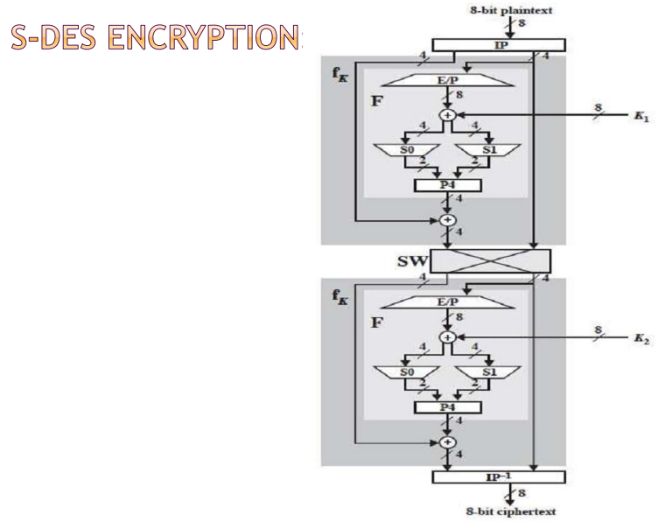

**2- Constants Decleration**

IP   = [2 6 3 1 4 8 5 7];
EP   = [4 1 2 3 2 3 4 1];
IP_1 = [4 1 3 5 7 2 8 6];
P4   = [2 4 3 1];
S0   = [1 0 3 2; 3 2 1 0; 0 2 1 3; 3 1 3 2];
S1   = [0 1 2 3; 2 0 1 3; 3 0 1 0; 2 1 0 3];

**3- Encryption**

plain = [1 0 1 0 1 0 1 0]

plain =      1     0     1     0     1     0     1     0


temp = perm(plain,IP,8);
left = temp(1:4);
right = temp(5:8);
[left_o,right_o] = ...
    SDES_Encryption(left,right,K1,EP,P4,S0,S1);
[left_o2,right_o2] =...
    SDES_Encryption(right_o,left_o,K2,EP,P4,S0,S1);
cipher = perm([left_o2,right_o2],IP_1,8)

cipher =      1     0     0     0     1     1     0     1


**4- Decryption**

cipher = [0 1 1 1 0 0 1 0]

cipher =      0     1     1     1     0     0     1     0


cipher = perm(cipher,IP,8);
left = cipher(1:4);
right = cipher(5:8);
[left_o,right_o] = ...
    SDES_Encryption(left,right,K2,EP,P4,S0,S1);
[left_o2,right_o2] =...
    SDES_Encryption(right_o,left_o,K1,EP,P4,S0,S1);
plain = perm([left_o2,right_o2],IP_1,8)

plain =      0     1     1     1     1     0     0     0
